figure;   
%f = tiledlayout(1,3);
%
%nexttile
hold on
%title(f,'Optochemical CO2 Sensor Design Tool_{TF}');
title('Optochemical CO2 Sensor Design Tool_{TF}');

pco2 = 0:0.001:80;
dye =0.001;
buffer =0.001;
%pathlength =0.001;
pathlength = 1; 
pka = 7.7;
disp('Sensing Media RECIPE');

Sensing Media RECIPE


disp(['buffer = ', num2str(buffer*1E3),' mM']);

buffer = 1 mM


disp(['dye = ', num2str(dye*1E6),' µM']);

dye = 1000 µM


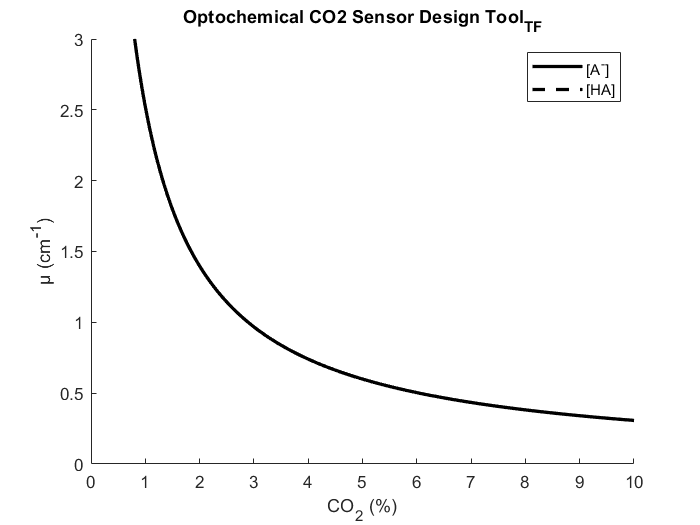

%disp('Sensing Media Thickness');
%disp(['pathlength = ' num2str(pathlength*1E2), ' cm']);
H_cubic = H_CO2(pco2,dye,buffer,pka);
out_array = CO2_H(H_cubic,dye,buffer,pka);
co2_cubic = 100*out_array(1,:)./760; %Convert to %CO2
[A_cubic,HA_cubic] = A_H(H_cubic,dye,pathlength,pka);






%e1 = 20000; %Extinction Coefficient of HA for HPTS @ 405 nm
%e2 = 24000; %Extinction Coefficient of A- for HPTS @ 450 nm
%pka = 7.7;

%pco2range = 0:0.01:10;
%pco2text="50";
%pco2 = str2double(pco2text);
%
%x = 0.000006607;
%c1 = (x/(x+1));
%dye = 1.5/(L*(0*c1+e2-e2*c1));
%disp(dye * L*(0*c1+e2-e2*c1));
%[~,buffer] = N_Dye_pCO2_ka(1,dye,pka,x);

%if dye >= buffer
%    disp('ERROR DYE CANNOT BE LARGER THAN BUFFER')
%end

% Use the quadratic solution to produce some [H+] values  
%y_cubic = H_CO2(pco2range,dye/6,buffer/10);

% Then use analytical solution [H+] to calculate pCO2
%out_array = CO2_H(y_cubic,dye/6,buffer/10);

% Use analytical solution to calculate HA_A or values
 
%[~,~,A,HA] = A_H(y_cubic,dye,L,1);

% check = 1;
% if check == 0
%     HA_A = A;
% elseif check == 1
%     HA_A = HA;
% end
%
% x_cubic = out_array(1,:);
plot(co2_cubic, A_cubic,'k',"LineWidth",2);
hold on
plot(co2_cubic, HA_cubic,'k--',"LineWidth",2);
xlim([0 10]);
ylim([0 3]);
legend('[A^{-}]','[HA]')
xlabel('CO_{2} (%)');
ylabel('µ (cm^{-1})');
hold off

%nexttile
%plot(x_cubic,10.^(-HA_A),'r',"LineWidth",2)
%xlim([0 pco2]);  
%ylim([0 2]);
%nexttile
%plot(x_cubic,-ec2*log(10)*10.^(-ec2*HA_A),'g',"LineWidth",2)
%xlim([0 pco2]);  
%ylim([0 1]);


%Original Solution by Rechnitz et al [Response Time Characteristics of the pCO2 Electrode]
% y = [H^+] mols/L
% x = pCO2 (mmHg)

% function varout = H_CO2(varargin)
%     varin = varargin{1};
%     dye = varargin{2};
%     nahco3 = varargin{3};
%     if length(varargin) == 4
%         m = varargin{4};
%     else
%         m = 1;
%     end
%     k0 = 4.47E-5;
%     k1 = 2.6E-3;
%     k2 = 1.72E-4;
%     kT = k0*k1*k2;
%     k3 = 5.59E-11;
%     kw = 1E-14;
%     ka = 10^(-7.7*m);
%     D1 = 0.2E-3;
%     D2 = 0.1E-3;
%     D = dye;
%     %
%     N1 = 1.4E-3;
%     N2 = 4.4E-3;
%     N3 = 8.4E-3;
%     N = nahco3;
%     %
%     %syms x y
%     %original = (y^3)-y*x*kT-2*x*kT*k3-y*kw+(y^2)*N == 0;
%     %optochemical = (y^3)-y*x*kT-2*x*kT*k3-y*kw+(y^2)*N-(y^2)*(ka*D/(ka+y)) == 0;
%     %opto_1 = -y*x*kT+(y^2)*N-(y^2)*(ka*D/(ka+y)) == 0;
%     %opto_2 = (y^2)*N+y*N*ka-y*D*ka-y*x*kT-x*kT*ka == 0 ;
%     % x = 1:0.1:40;
%     x = varin;
%     y = (sqrt((-D*ka + ka*N-kT*x).^2+4*ka*N*kT*x)+D*ka-ka*N+kT*x)/(2*N);
%     y2 = (x*kT+D*ka)/N;
%     y3 = 100*(y2-y)./y;
%     varout = y;
% end
% function varout = CO2_H(varargin)
%     %Inverted function so that we can solve the equation easily
%     %Original Solution by Rechnitz et al [Response Time Characteristics of the pCO2 Electrode]
%     % y = [H^+] mols/L
%     % x = pCO2 (mmHg)
%     varin = varargin{1};
%     dye = varargin{2};
%     nahco3 = varargin{3};
%     if length(varargin) == 4
%         m = varargin{4};
%     else
%         m = 1;
%     end
%     k0 = 4.47E-5;
%     k1 = 2.6E-3;
%     k2 = 1.72E-4;
%     kT = k0*k1*k2;
%     k3 = 5.59E-11;
%     kw = 1E-14;
%     ka = 10^(-7.7*m);
%     D1 = 0.2E-3;
%     D2 = 0.1E-3;
%     D = dye;
%     %
%     N1 = 1.4E-3;
%     N2 = 4.4E-3;
%     N3 = 8.4E-3;
%     N = nahco3;
%     %
%     %syms x y
%     %original = (y^3)-y*x*kT-2*x*kT*k3-y*kw+(y^2)*N == 0;
%     %optochemical = (y^3)-y*x*kT-2*x*kT*k3-y*kw+(y^2)*N-(y^2)*(ka*D/(ka+y)) == 0;
%     
%     %( (y.^3)-y*(1E-14)+(y.^2)*N-(y.^2).*(10^(-7.7)*2.0000E-04./(10^(-7.7)+y)) )./(y.*1.99898400000000E-11+2*1.99898400000000E-11*5.59E-11);
%     
%     %opto_1 = -y*x*kT+(y^2)*N-(y^2)*(ka*D/(ka+y)) == 0;
%     %opto_2 = (y^2)*N+y*N*ka-y*D*ka-y*x*kT-x*kT*ka == 0 ;    
%     y = varin;
%     x_num = (y.^3)-y*kw+(y.^2)*N-(y.^2).*(ka*D./(ka+y));
%     x_den = y*kT+2*kT*k3;
%     x = x_num ./ x_den;
%     y_quad = (sqrt((-D*ka + ka*N-kT*x).^2+4*ka*N*kT*x)+D*ka-ka*N+kT*x)/(2*N);
%     y_lin = (x*kT+D*ka)/N;  
%     varout = [x;y_quad;y_lin];
% end

